% Load data file
optResults1 = load("BayesianOptimiserBird10InitAEI.mat")

optResults1 = struct with fields:
    simulationResults: {1×30 cell}


optResults2 = load("LVBayesianBird10InitAEI.mat")

optResults2 = struct with fields:
    simulationResults: {1×30 cell}


optResults3 = load("SNOBFITBird10InitOpt.mat")

optResults3 = struct with fields:
    simulationResults: {1×30 cell}


optResults4 = load("BayesianOptimiserBird10InitEI20.mat")

optResults4 = struct with fields:
    simulationResults: {1×30 cell}


optResults5 = load("LVBayesianBird10InitEI20Opt.mat")

optResults5 = struct with fields:
    simulationResults: {1×30 cell}


optResults1 = optResults1.simulationResults;
optResults2 = optResults2.simulationResults;
optResults3 = optResults3.simulationResults;
optResults4 = optResults4.simulationResults;
optResults5 = optResults5.simulationResults;

minResults1 = []


minResults1 =

     []



for x = 1:length(optResults1)
    minResults1(x) = min(optResults1{1,x}.minResponceReturn);
end

minResults2 = []


minResults2 =

     []



for x = 1:length(optResults2)
    minResults2(x) = min(optResults2{1,x}.minResponceReturn);
end

minResults3 = []


minResults3 =

     []



for x = 1:length(optResults3)
    minResults3(x) = min(optResults3{1,x}.minResponceReturn);
end

minResults4 = []


minResults4 =

     []



for x = 1:length(optResults4)
    minResults4(x) = min(optResults4{1,x}.minResponceReturn);
end

minResults5 = []


minResults5 =

     []



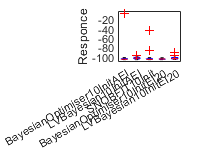

for x = 1:length(optResults5)
    minResults5(x) = min(optResults5{1,x}.minResponceReturn);
end

minResults = [minResults1; minResults2; minResults3; minResults4; minResults5];
%minResults = minResults2

%boxplot(minResults','Labels',{'BayesianOptimser','LVBayesian', 'SNOBFIT'})
boxplot(minResults','Labels',{'BayesianOptimiser10InitAEI', 'LVBayesian10InitAEI','SNOBFIT10Init', 'BayesianOptimiser10InitEI20', 'LVBayesian10InitEI20'})
ylabel("Responce")